# Logistic Regression for Titanic data classification 

## Load the Titanic data and show it


Train= readtable('titanic\train.csv');
Test = readtable('titanic\test.csv');
head(Train)

ans = 8×12 table
    PassengerId    Survived    Pclass                            Name                               Sex       Age    SibSp    Parch          Ticket           Fare      Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ________    ___    _____    _____    __________________    _______    ______    ________

         1            0          3       'Braund, Mr. Owen Harris'                                'male'       22      1        0      'A/5 21171'              7.25    ''          'S'   
         2            1          1       'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'    'female'     38      1        0      'PC 17599'            71.2833    'C85'       'C'   
         3            1          3       'Heikkinen, Miss. Laina'                                 'female'     26      0        0      'STON/O2. 3101282'      7.925    ''          'S'   
         4            1          1       'Futre

## Make the prediction by "sex"


disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'))

                Sex       GroupCount      mean_Survived  
              ________    __________    _________________

    male      'male'         577        0.188908145580589
    female    'female'       314         0.74203821656051



gendermdl = grpstats(Train(:,{'Survived','Sex'}), {'Survived','Sex'});
all_female = (gendermdl.GroupCount('0_male') + gendermdl.GroupCount('1_female'))/(577+314);
disp(all_female)

   0.786756453423120



## Preprocess the NaN values

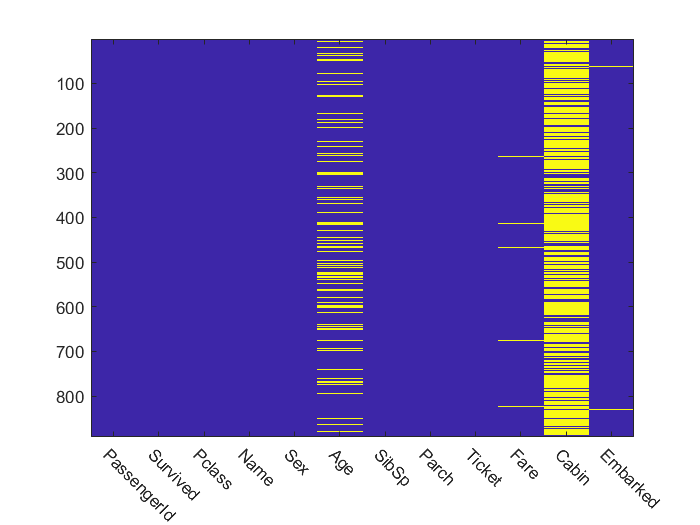

Train.Fare(Train.Fare == 0) = NaN;      % treat 0 fare as NaN
Train.Fare(Train.Fare == 0) = NaN;        % treat 0 fare as NaN
vars = Train.Properties.VariableNames;  % extract column names
figure
imagesc(ismissing(Train))
set(gca,'XTick', 1:12,'XTickLabel',vars);
xtickangle(-45)

% Using the average age replace NaN age
avgAge = nanmean(Train.Age)             % get average age

avgAge =   29.699117647058820


Train.Age(isnan(Train.Age)) = avgAge;   % replace NaN with the average
Test.Age(isnan(Test.Age)) = avgAge; 


% Replace the NaN Fare with the average fare of the correspoinding Pclass
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % get class average
disp(fare)

         Pclass    GroupCount       mean_Fare    
         ______    __________    ________________

    1      1          216        86.1488744075829
    2      2          184        21.3586612359551
    3      3          491        13.7878749486653



for i = 1:height(fare) % for each |Pclass|
    % apply the Pclass average to missing values
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end

% Multi Cabins，No Cabin etc.

train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false);
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false);
 
% count the number of tokens
Train.nCabins = cellfun(@length, train_cabins);
Test.nCabins = cellfun(@length, test_cabins);
 
% deal with exceptions - only the first class people had multiple cabins
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;
 
% if |Cabin| is empty, then |nCabins| should be 0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0;
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

% Embarked is not available
% get most frequent value
disp(grpstats(Train(:,{'Survived','Embarked'}), 'Embarked'))

         Embarked    GroupCount      mean_Survived  
         ________    __________    _________________

    S      'S'          644         0.33695652173913
    C      'C'          168        0.553571428571429
    Q      'Q'           77         0.38961038961039



 
% apply it to missling value
for i = 1 : 891
    if isempty(Train.Embarked{i})
        Train.Embarked{i}='S';
    end
end
 
for i = 1 : 418
    if isempty(Test.Embarked{i})
        Test.Embarked{i}='S';
    end
end
 
% convert the data type from categorical to double
Train.Embarked = double(cell2mat(Train.Embarked));
Test.Embarked = double(cell2mat(Test.Embarked));

% change Sex to tpye "double"
for i = 1 : 891
    if strcmp(Train.Sex{i} ,'male')
        Train.Sex{i}=1;
    else
        Train.Sex{i}=0;
    end
end
 
for i = 1 : 418
    if strcmp(Test.Sex{i} ,'male')
        Test.Sex{i}=1;
    else
        Test.Sex{i}=0;
    end
end
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);

% Del some columns
Train(:,{'Name','Ticket','Cabin'}) = [];
Test(:,{'Name','Ticket','Cabin'}) = [];


## Visulization

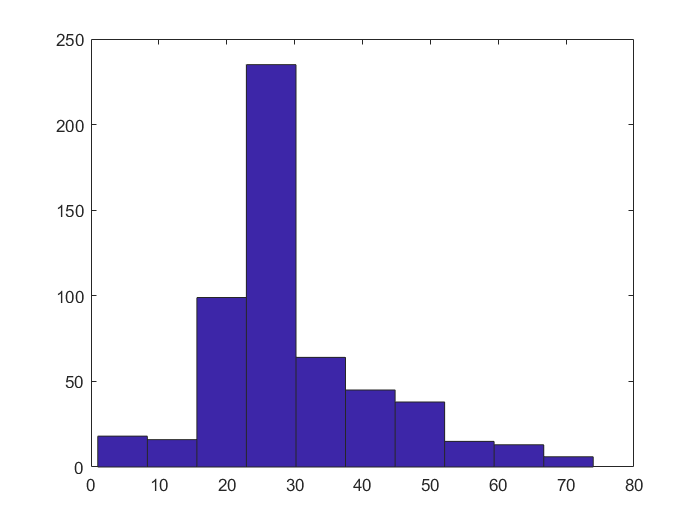


% Age - survived
figure
hist (Train.Age(Train.Survived == 0))   % age histogram of non-survivers

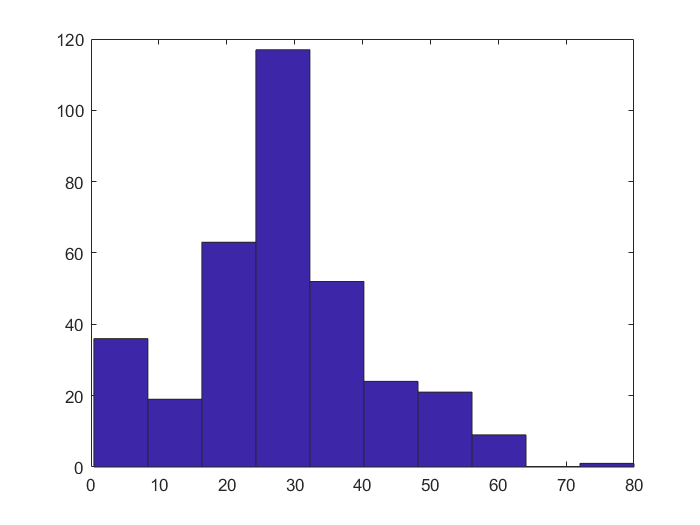

figure
hist (Train.Age(Train.Survived == 1))   % age histogram of survi

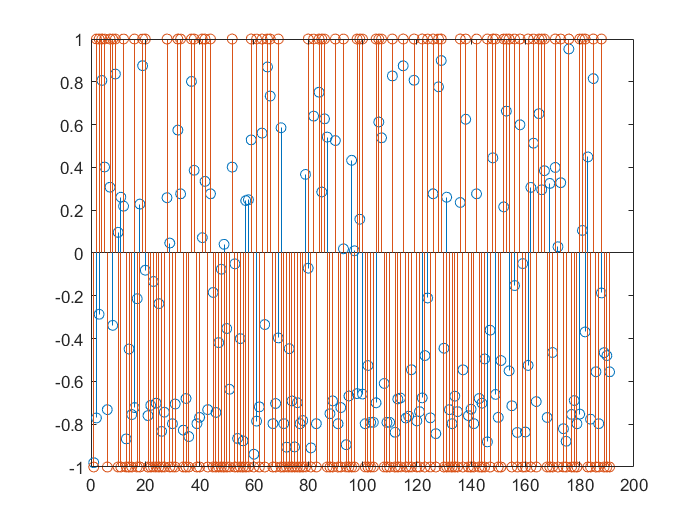

data = Train.Variables;
t = data(:,3:10);
l = data(:,2);
X = t';
X = zscore(X,0,2);
X = [X;ones(1,891)];
y = (l*2-1)';
idx = randperm(891);
X_train = X(:,idx(1:700));
y_train = y(idx(1:700));
X_test = X(:,idx(701:891));
y_test = y(idx(701:891));
y_aug = repmat(y_train,9,1);

w = ones(1,9)';
alpha = 0.001;
for iter = 1:10000
    X_y = y_aug.*X_train;
    outp = my_sigd(w,X_y);
    NLL(iter) = - sum(log(outp));
    dldw = my_gradient(w,X_y);
    w = w - alpha*dldw;
end

p1 = my_sigd(w,X_test);
pred = p1*2-1;
stem(pred);
hold on
stem(y_test);

p1(p1>=0.5) = 1;
p1(p1<0.5) = -1;
sum(y_test == p1)/191

ans =    0.801047120418848


## sigmoid

function output = my_sigd(w,x)

    temp =exp(-w'*x);
    output = 1./(1+temp);
end


### Gradient

function dldw =my_gradient(w,x)
    temp =exp(w'*x);
    output = 1./(1+temp).*x;  
    dldw = -sum(output,2);
end

